load("workspace_cnn.mat") % in the case that CNN_script.m is not open

Code to convert original images into images in a format suitable for use on the network

original = imageDatastore('C:\Users\Diego\Desktop\matprojects\MyDigitDatasetCopy', ...
        'IncludeSubfolders',true,'LabelSource','foldernames');

for i = 1:50 % 50 = número de imágenes
    location = original.Files{i};
    orig_image = imread(location);
    % process image to have 28x28 size, single channel and with colors
    % inverted (since in the original the number is written on a white background)
    new_image = imresize(rgb2gray(imcomplement(orig_image)),[28 28]);
    imwrite(new_image,location);
end

Unable to resolve the name myDigitData.Files.

Code to obtain activations of each layer for the first ten digits

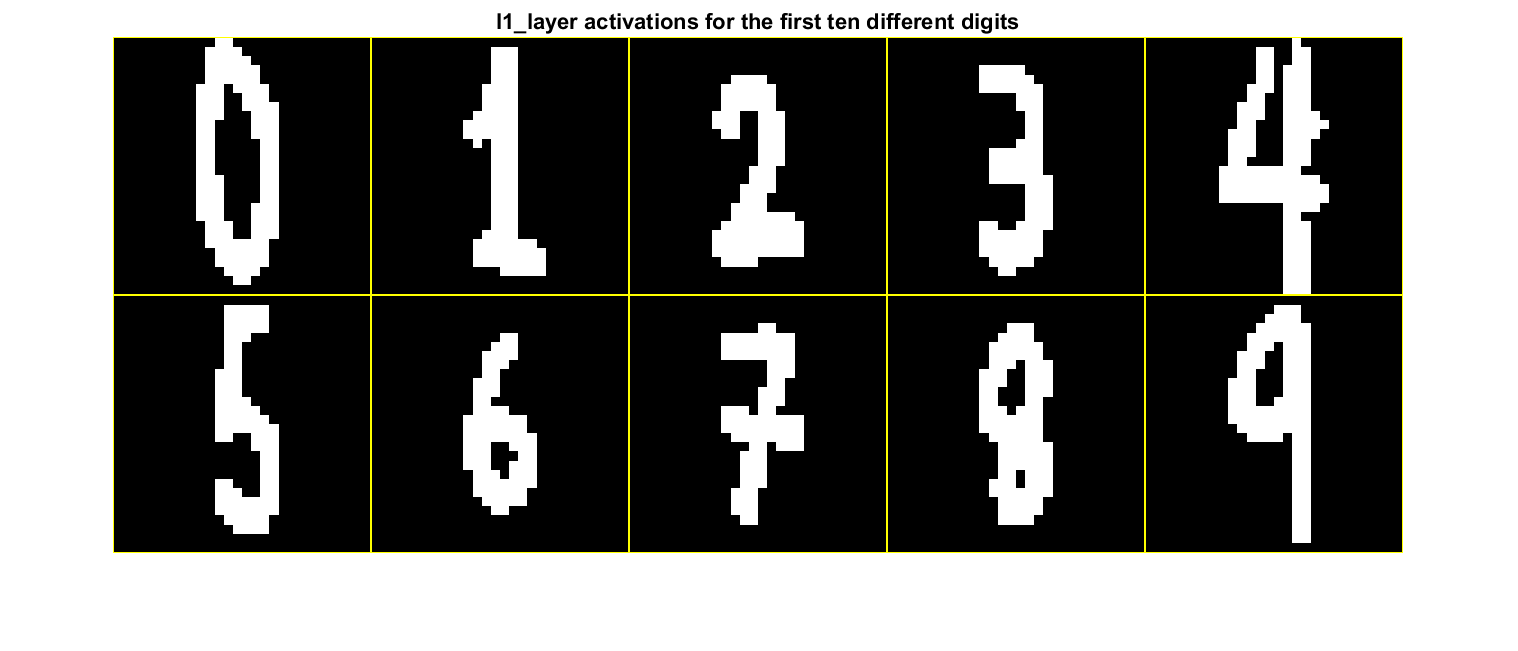

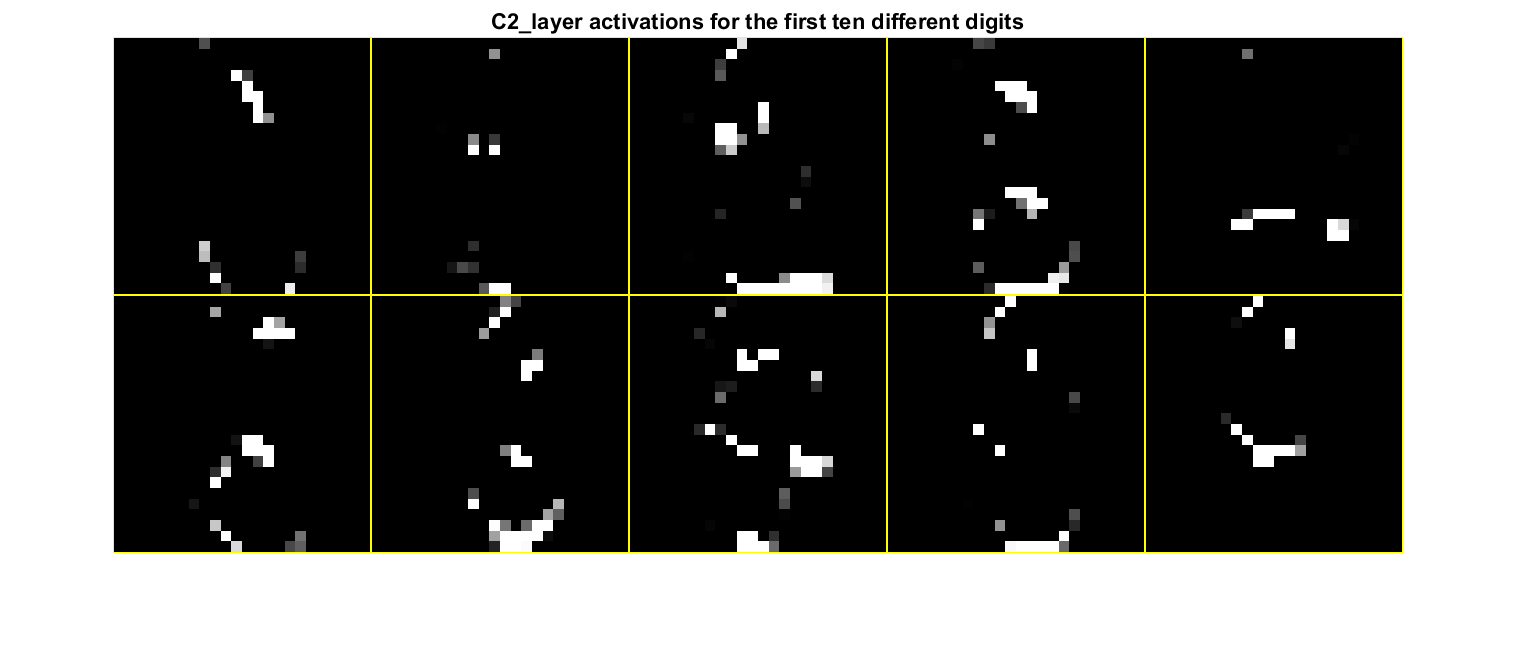

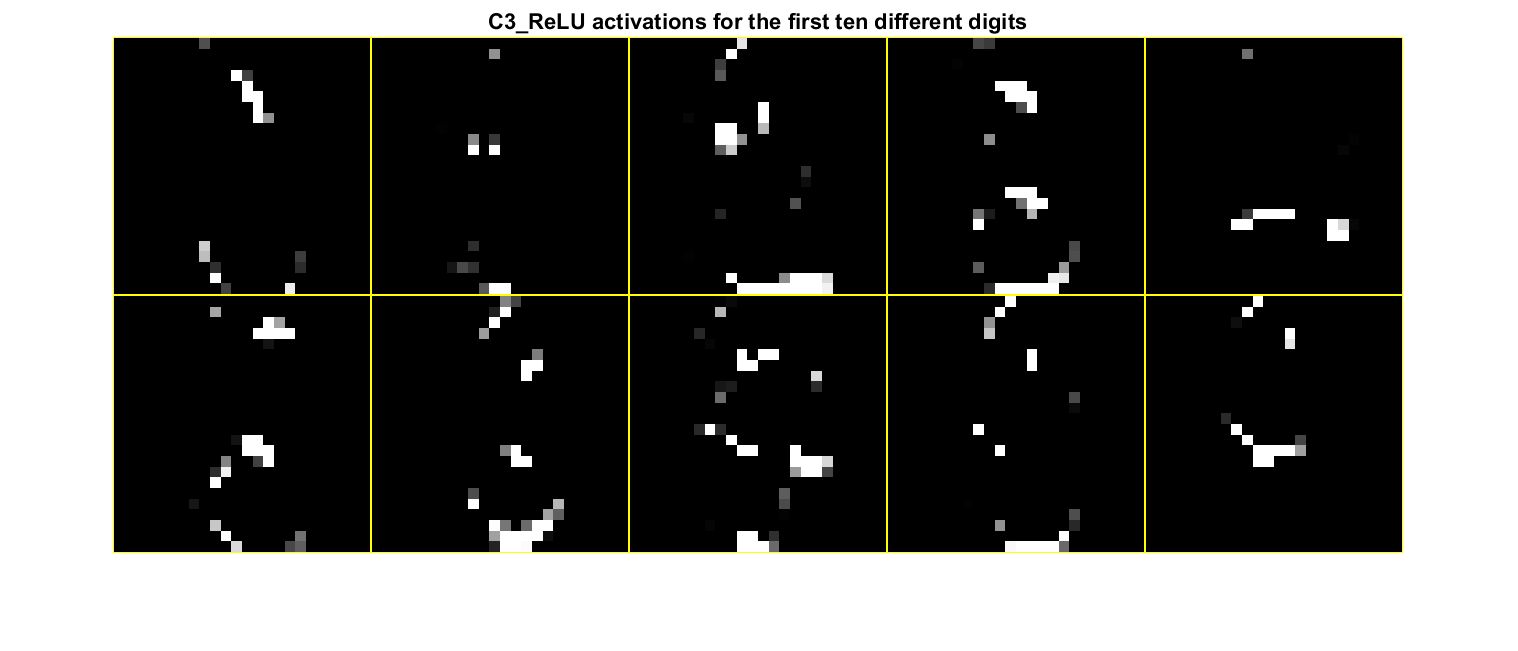

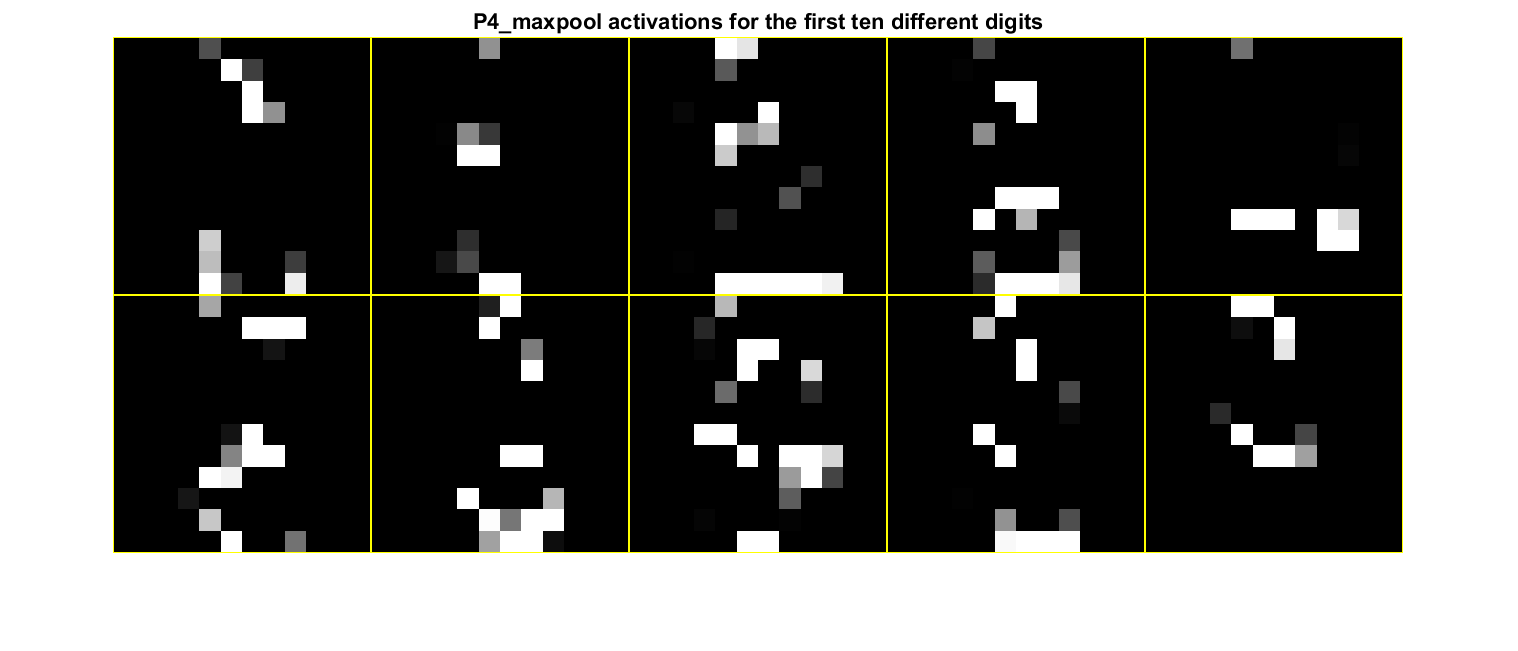

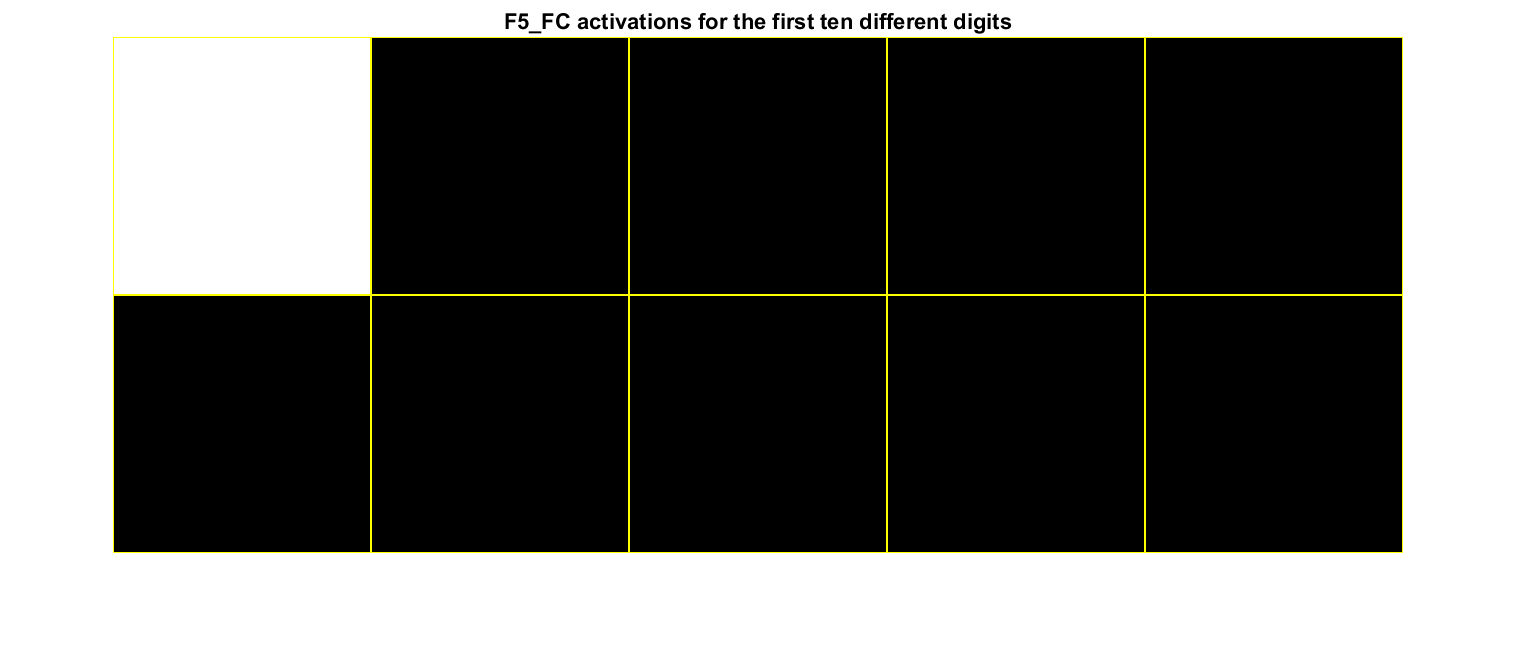

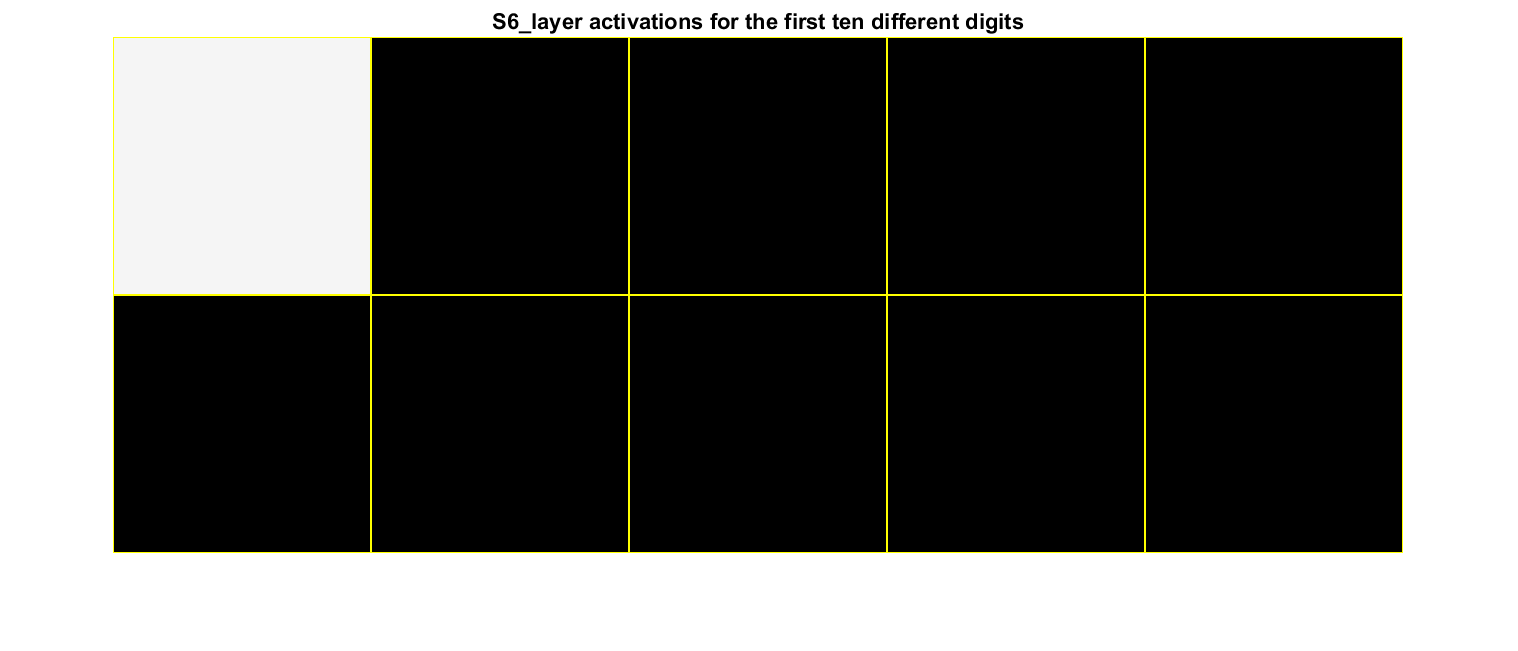

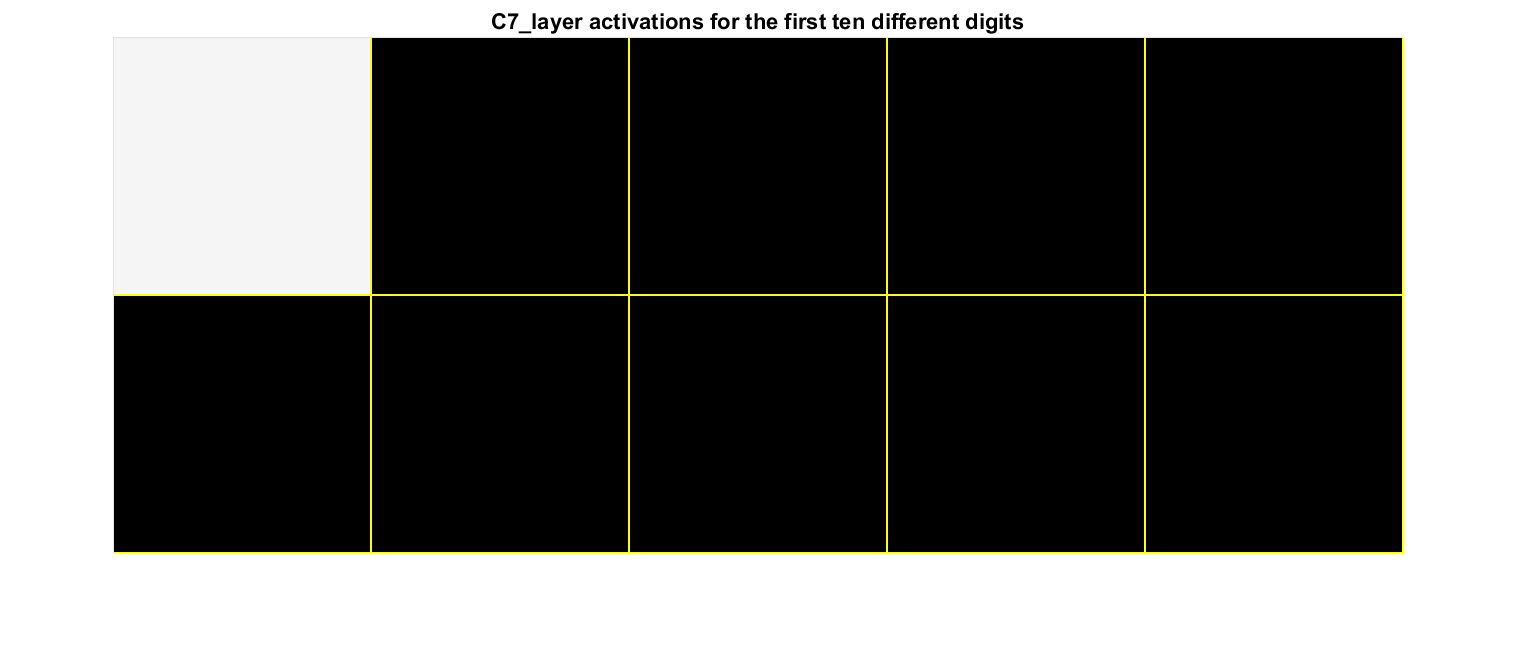

firstnums = 1:5:50;
% firstnums = 1:1000:10000; % if you want to show MNIST digits

for layer = 1:7
    all_activs = [];
    for dig = 1:10
        % filename = digitData.Files{firstnums(dig)}; % if you want to show
        % MNIST digits
        filename = MyDigitData.Files{firstnums(dig)};
        im = imread(filename);
        layername = convnet.Layers(layer).Name;
        activ = activations(convnet,im,layername);
        if layer == 1
            firstmatrix = activ(:,:,1);
        else % conditional allows to extract activations from matrices or neurons ~= than first
            firstmatrix = activ(:,:,4);
        end
        all_activs = cat(3,all_activs,firstmatrix); % concatenate activations in 3d array
    end
    figure
    montage(all_activs,'Size',[2 5],'BorderSize',[1 1],'BackgroundColor','yellow' )
    title(strcat(layername,' activations for the first ten different digits'),...
        'Interpreter','none')
end

Code for observing the effect of the ReLU transformation

convol = activations(convnet,im,'C2_layer');
convol(:,:,1)

ans = 24×24 single matrix
   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0418   -0.7649   -0.3949    1.3239   -9.0192  -24.6311  -25.0844  -23.1780  -23.8912  -10.8127   -1.1400   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.3209   -1.0289    1.1486   -4.2348  -21.4590  -22.8406  -19.2601  -23.9955  -26.9748  -16.8684   -2.3310   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0242   -0.7906    0.0547   -0.8848  -15.6647  -25.3475  -14.7706   -7.8766  -12.6198  -24.3764  -20.6764   -3.7459   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.1996   -0.9566   -0.8404   -7.5815  -21.1332  -22.6496  -10.6559    2.1961   -4.0749  -20.1808  -21.2428   -5.1933   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016   -0.0016
   -0.0016


relu = activations(convnet,im,'C3_ReLU');
relu(:,:,1)

ans = 24×24 single matrix
         0         0         0         0         0         0         0         0         0         0    1.3239         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.1486         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0    0.0547         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0    2.1961         0         0         0         0         0         0         0         0         0         0
         0

Code to replicate processing that takes place in the classification layer

firstnums = 1:5:50;
C7layer_preds = YTest(firstnums);
all_losses = [];

for dig = 1:10
    filename = MyDigitData.Files{firstnums(dig)};
    im = imread(filename);
    softmax_output = dlarray(reshape(activations(convnet,im,'S6_layer'),[10 1]));
    loss_dig = zeros([10 1]);
    
    % cross-entropy for each neuron
    for i = 1:10
        probs = zeros([10 1]);
        probs(i) = 1; % e.g. prob. vector for input "0" -> [1 0 0 0 0 0 0 0 0 0]
        loss_dig(i) = crossentropy(softmax_output,probs,'DataFormat','U');
    end
    all_losses = cat(2,all_losses,loss_dig);
end

all_losses

all_losses =     0.0393   15.9424   15.9424   15.9424   12.9404   15.9424   15.9424   15.9424   15.9424   15.9424
    6.8107    0.0983    5.9559   15.9424   11.2485    8.5116   14.3181   11.3292    7.5997   12.9275
    8.8065    3.1630    0.0089   15.9424    5.6397   15.9424   15.9424   12.8899   14.7169   15.9424
    4.8256    4.7518    9.4745    0.0000    5.2826    1.3349   15.9424    0.0159    1.5228    4.4096
   11.7119   13.3217   13.4118   15.9424    4.5283   15.9424   15.9424    8.5197   11.1392   13.6999
   15.9424    3.9942   15.9424   15.9424   11.4982    0.3086    7.6679   15.9424   15.6813   15.9424
    8.3009   10.3855   15.9424   15.9424    5.6748    6.2309    0.0006   12.8546    7.9154   14.8059
    5.9808    3.8129    8.6018   15.9424    9.3683   15.9424   15.9424    6.1240   10.4631    4.1213
    3.6399    6.8597    5.1101   15.9424    0.6118    8.9716    9.2139    4.3185    0.2472    0.0360
    8.2114    6.7884   15.9424   15.9424    0.8332   15.9424   15.9424   15.94


[~,idx_of_min] = min(all_losses);
preds_by_crossentropy = categorical((idx_of_min-1)');

% comparison of network predictions and predictions obtained after manually
% calculate cross-entropy
[C7layer_preds preds_by_crossentropy]

ans = 10×2 categorical array
     0      0 
     1      1 
     2      2 
     3      3 
     8      8 
     5      5 
     6      6 
     3      3 
     8      8 
     8      8 


Code for extracting cross entropies when presenting first nine

all_losses(:,10)

ans =    15.9424
   12.9275
   15.9424
    4.4096
   13.6999
   15.9424
   14.8059
    4.1213
    0.0360
    4.9655
